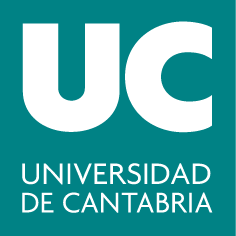

***Grados en Ingeniería Eléctrica y en  Ingeniería en Electrónica Industrial y Automática***

**Métodos Matemáticos para Ingeniería**

**Bloque II: Métodos Numéricos**

# **2. Resolución de ecuaciones escalares no lineales**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

## 2.1. Definiciones

Se define la **raíz de una ecuación** como el valor de $$x$ $que hace $$f(x) = 0$$.

Los métodos numéricos para encontrar raíces se encuentran en dos áreas de problemas relacionados, pero fundamentalmente distintos:

-  La determinación de raíces reales de ecuaciones algebraicas y trascendentes: determinar el valor de **una sola raíz** real basándose en un conocimiento previo de su posición aproximada.

- La determinación de todas las raíces reales y complejas de polinomios:  determinar sistemáticamente **todas las raíces** del polinomio en lugar de sólo una raíz real dada una posición aproximada.

En este curso se consideran los **métodos iterativos**. El algoritmo de un método iterativo consiste en los siguientes pasos:

- Tomar una aproximación inicial de la solución: $$x_0$$ (valor de partida)

- Generar una sucesión de puntos: $$$x_0 \rightarrow x_1 \rightarrow x_2 \rightarrow \ldots $$$

- La sucesión generada $$\{ x_k \}_{k=0}^{\infty}$$ cumpla $	$$\lim_{k \rightarrow \infty} x_k = x^*$$$, donde $ $x^*$$  ese la solución  de la ecuación.

Sea $$\{ x_k \}_{k=0}^{\infty}$$ una sucesión de números reales que converge hacia un punto $$x^*$$. Diremos que el **orden de convergencia** es $$p$ $(con $$p \geq 1$$) si existe una constante $$C_p >0$$ tal que


$$	$$|x_{k+1} -x^*| \leq C_p |x_k - x^*|^p, \quad \forall k \geq 0$$$$


Cuanto mayor es el orden de convergencia, más rápido converge el método.

**Clasificación de los métodos numéricos:**

* a veces la convergencia es muy lenta.

Para la aproximación inicial (el punto o el intervalo de partida), se puede utilizar el **método gráfico**:

- Graficar la función $$f(x)$;$

- Observar dónde cruza el eje $$x$$;

- Este punto ofrece una aproximación inicial de la raíz.

## 2.2. Métodos cerrados

Los métodos cerrados utilizan intervalos para encontrar raíces. Estos métodos comienzan con intervalos que contienen la raíz y luego reducen sistemáticamente el tamaño del intervalo. Se basan en el hecho de que una función cambia de signo en la vecindad de una raíz (Teorema de Bolzano). 

**Teorema de Bolzano**: Si $$f(x)$$ es continua en $$[a,b]$$ y $$$f(a)\cdot f(b) < 0,$$$ entonces 	en $$[a, b]$$ hay un número impar (al menos 1) de raíces.

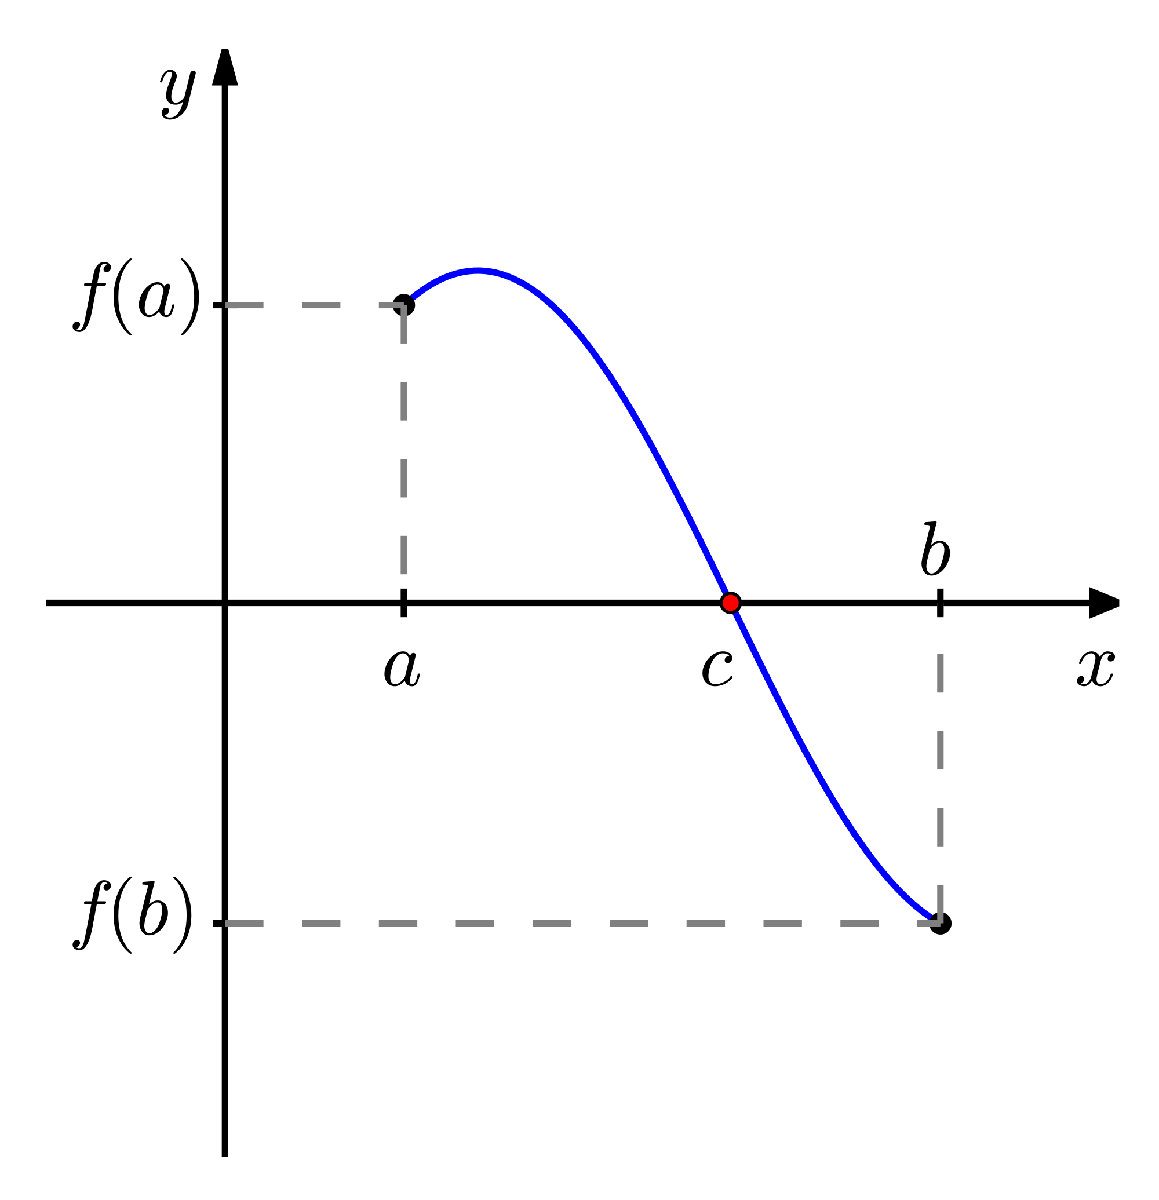

#### Método de bisección

El método de bisección consiste en acercar sistemáticamente los extremos de un intervalo hasta obtener uno de anchura suficientemente pequeña que contenga la raíz. El proceso de subdivisión del intervalo implica tomar el punto medio del intervalo y determinar en cuál de los dos subintervalos se encuentra la raíz.

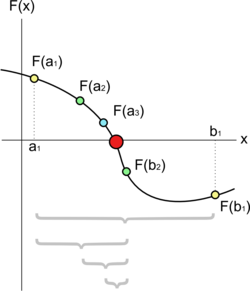

**Algoritmo del método de bisección:**

- Eligir valores $$a$$ y $ $b$$, que encierren la raíz: $$ f(a) \cdot f(b) < 0$$

- Calcular la aproximación de la raíz: $$x_r = \frac{a+b}{2}$$

-  Determinar subintervalo:

		Si$ $ f(a) \cdot f(x_r) < 0$$, entonces poner $$b = x_r$$

                Si $$ f(a) \cdot f(x_r) > 0$$, entonces poner $$a = x_r$$

                Si $$ f(a) \cdot f(x_r) = 0$$, entonces $$x_r$$ es la raíz, terminar el cálculo				

	   4. Volver al paso 2.

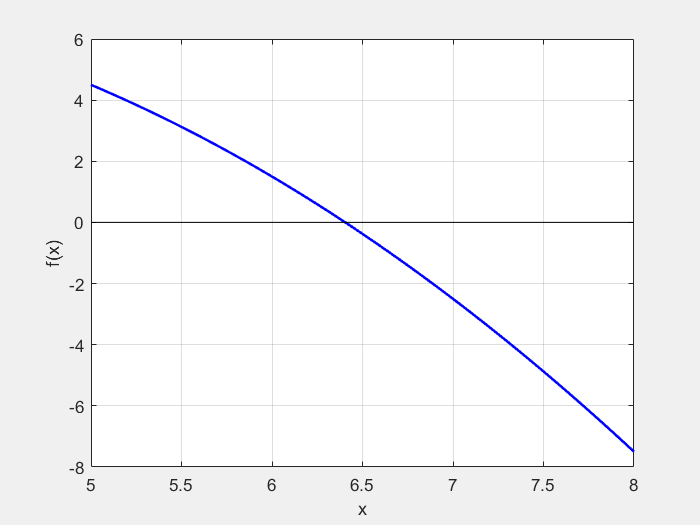

**Ejemplo:** Resolver la ecuación $f(x)  = \cos(x) + 1 -x =0$

1. Representamos graficamente la función para localizar la raíz:

clearvars              % borramos todas las variables de Workspace
f = @(x) cos(x)+1-x;    % definimos f(x) como una función anónima
fplot(f)                % representamos la función
grid on                 % añadimos la cuadrícula

Podemos elegir como intervalo inicial $[0, \, 5]$: 

a = 0; b = 5;

Calculamos el punto medio del intervalo y evaluamos la función en este punto:

xr = (a+b)/2;
fr = f(xr);
fprintf("f(%f) = %f, \tf(%f) = %f, \tf(%f) = %f \n", a,f(a),xr,fr,b,f(b))

En el intervalo $[a, \, x_r]$ la función cambia el signo, por lo tanto la raíz está en este subintervalo, ponemos $$b = x_r$$:

b=xr;

Y repetimos todos los pasos:

xr = (a+b)/2;
fr = f(xr);
fprintf("f(%f) = %f, \tf(%f) = %f, \tf(%f) = %f \nLongitud del intervalo: %f", a,f(a),xr,fr,b,f(b),b-a)

Ahora el subintervalo que contiene la raíz es $[x_r, \, b],$ por lo tanto

a= xr;

Y repetimos todos los pasos:

xr = (a+b)/2;
fr = f(xr);
fprintf("f(%f) = %f, \tf(%f) = %f, \tf(%f) = %f \nLongitud del intervalo: %f", a,f(a),xr,fr,b,f(b),b-a)

... Así seguimos hasta obtener un intervalo de anchura suficientemente pequeña que contenga la raíz.

**Ejercicio**: Continua las iteraciones hasta que la longitud del intervalo sea menor que $10^{-3}$. ¿Cuántas iteraciones has realizado?

 Para comprobar el resultado:

f = @(x)cos(x)+1-x; a = 0; b = 5; epsilon = 0.001;
[x_r, k, ak,bk] = biseccion( f, a, b, epsilon);
fprintf("xr = %f,\nf(%f) = %.4e,\nLongitud del itervalo: %.4e\nNúmero de iteraciones: %d\n", x_r,x_r, f(x_r),bk-ak,k)

Una posible implementación del método de bisección

Notemos que la longitud del intervalo en cada iteración es la mitad del intervalo de la iteración anterior. Además, la sucesión de los extremos izquierdos de estos intervalos es creciente, mientras que la sucesión de los extremos derechos es decreciente:


$$a_0 \leq a_1\leq a_2\leq \ldots \leq a_n \leq \ldots \leq b_n\leq \ldots\leq b_2\leq b_1 \leq b_0 $$


**Convergencia del método de bisección**

Supongamos que $f(x)$ es una función continua en el intervalo $[a, b]$ y que $f(a) $ y $f(b)$ tienen signos distintos. Sea $\{c_n\}_{n = 0}^{\infty}$ la sucesión de puntos medios de los intervalos generados por el método de bisección. Entonces existe un número $x_r \in [a,b]$ tal que $f(x_r) = 0$ y, además, 

$|x_r - c_n| \leq \frac{b-a}{2^{n+1}}$  para $n = 0,1,\ldots$,

en particular la sucesión$\{c_n\}_{n = 0}^{\infty}$ converge a la raíz $x_r$.

Notas importantes

- Si $$f(a)f(b) <0$$ puede haber más de una raíz, al menos habrá una. El método sólo encuentra una de ellas.

- Si $$f(x)$$ no es continua en $$[a,b]$$ no está garantizado el funcionamiento del método.

- Si $$f(a)f(b) > 0$$ el método no tiene garantizado el funcionamiento.

- Se puede calcular el número de iteraciones $ $N$$ que deben realizarse para cometer un error absoluto menor o igual de un $$\epsilon$$ prefijado:

	$
	$$N \geq \frac{\ln \left(\frac{b-a}{\epsilon}\right)}{\ln 2}$$$, 

#### Método de la falsa posición

Otro algoritmo popular es el método de la *régula falsi* o método de la posición falsa. Se basa en la misma idea del método de bisección, pero busca mejorar la convergencia utilizando una recta  secante $L$ que conecta los puntos extremos del intervalo. Esta secante está definida por la ecuación 


$$\frac{y-f(b)}{x-b} = \frac{f(a)-f(b)}{a-b}$$


Hallamos el punto donde la secante $L$ cruza el eje Ox:

$\frac{0-f(b)}{x_r-b} = \frac{f(b)-f(a)}{b-a}, $ de donde $x_r = b - f(b)\frac{b-a}{f(b)- f(a)}$

Las tres posibilidades son las mismas que antes:

- Si $ $ f(a) \cdot f(x_r) < 0$$, entonces hay una raíz en $[a, x_r]$

- Si $$ f(a) \cdot f(x_r) > 0$$, entonces hay una raíz en $[x_r, b]$

- Si $$ f(a) \cdot f(x_r) = 0$$, entonces $$x_r$$ es la raíz.

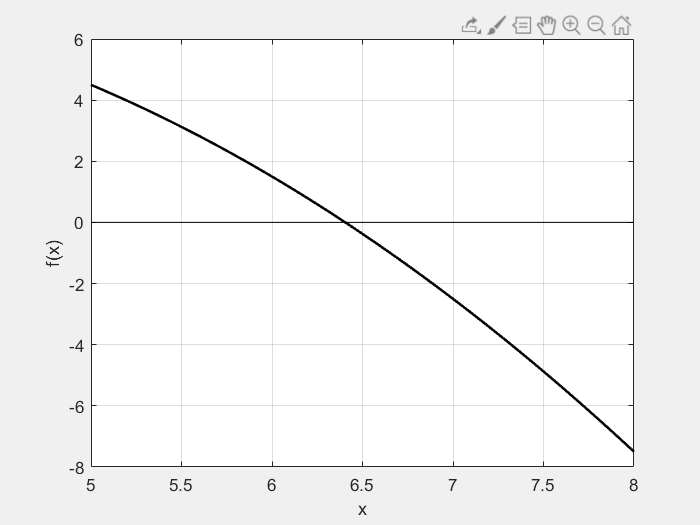

**Ejercicio: **Implementa el método de la posición falsa para resolver la ecuación $f(x)  = \cos(x) + 1 -x =0$.

% escribe el código aquí





## 2.3. Métodos abiertos

Características comunes de los métodos abiertos:

- Se basan en fórmulas requieren un único valor de inicio o si requieren dos, no es necesario que encierren a la raíz

- No está garantizada la convergencia

- En caso de converger, lo hacen mucho más 	rápido que los métodos cerrados.

#### Iteración de punto fijo

Un **punto fijo** de una función $g(x)$ es un número real $P$ tal que $g(P) = P$

**Idea del método**: Arreglar la ecuación $$f(x) = 0$$ de tal modo que $$x$$ esté del lado izquierdo de la ecuación:

	
$$	$x = g(x)$.$$


**Algoritmo del método**

- Se despeja de manera: $$x=g(x)$$.

- Resolviendo la desigualdad $$|g' (x)|\leq 1$$, obtener el rango de valores en los cuales está el punto fijo llamado $$$x_0$$$.

- Partiendo de $$x_0$$ buscar la raíz haciendo iteraciones $$x_{k+1} = g(x_k)$, $k=0, 1, \ldots$$.

- Citerios de paro:

- 
$$|f(x_k)|<\epsilon$$
 

- 
$$$R_k= \frac{|x_{k+1}-x_k|}{|x_{k+1}|}< \epsilon$$$


- Se alcanza el número máximo de iteraciones

**Ejemplo: **Resolvemos la ecuación $f(x)  = \cos(x) + 1 -x =0$ usando las iteraciones de punto fijo con tolerancia $\epsilon = 10^{-2}$.

- Despejamos $x$: $x = \cos x+1$

- $g'(x) = - sen \, x$, por tanto $$|g' (x)|\leq 1$$ se cumple $\forall x\in \mathbb{R}$. Podemos elegir cualquer punto como aproximación inicial, por ejemplo, $x_0 =1.$

- El proceso iterativo: $x_{k+1} = \cos(x_k)+1$

clearvars % borramos todo de la memoria
f = @(x) cos(x)+1-x; % f(x)
g = @(x) cos(x)+1;   % iteración de punto fijo g(x) = x
x = 1; % aproximación inicial
epsilon = 1e-2; % tolerancia

for k = 1:200 % limitamos el número máximo de iteraciones para evitar bucles infinitos
    x(k+1) = g(x(k));
    if abs(f(x(k+1)))< epsilon || abs(x(k+1) - x(k))< epsilon*max(1,abs(x(k+1)))
        break
    end
end
x_r = x(end);
fprintf("xr = %f,\nf(%f) = %.4e,\nNúmero de iteraciones: %d\n", x_r,x_r,f(x_r),k+1)
plot(1:k+1,x,'r')
grid on
xlabel('Iteraciones, k')
ylabel('x_k')

**Ejercicio: **Elige diferentes valores para la aproximación inicial. Observa y comenta los resultados. 

**Teorema del valor medio:** Si una función$ $g(x)$$ y su primer derivada son continuas en un intervalo $$a \leq x \leq b$$, entonces existe al menos un $\xi\in[a,b]$ tal que

	
$$$$g'(\xi) = \frac{g(b)-g(a)}{b-a}$$$$


**Análisis de la convergencia	**

Definimos la solución exacta $$x_r = g(x_r)$$. Restando, se obtiene $$$x_r - x_{k+1} = g(x_r) - g(x_k)$$$

Del teorema del valor medio, existe al menos un punto  $$\xi$$ entre $$x_k$ $y $$x_r$$ que tiene una pendiente, denotada por $$g'(x)$$, que es paralela a la línea que une $$g(x_{k})$$ con $$g(x_r)$$:


$$$$g(x_r) - g(x_{k}) = g'(\xi)(x_r-x_k)$$$$


Así, $$x_r - x_{k+1} =g'(\xi)(x_r-x_k)$$. Si el error verdadero en la iteración $$k$$ se define como $$E_k = x_r-x_k$$, entonces


$$$$E_{k+1} = g'(\xi)E_k$$$$


En consecuencia, si $$|g'(x)| < 1$$, entonces los errores disminuyen con cada iteración. 

Si $$|g'(x)| > 1$$, los errores crecen. Además, si la derivada es positiva, los errores serán positivos y, por lo tanto, la solución iterativa será monótona. Si la derivada es negativa, entonces los errores oscilarán.

La iteración simple de punto fijo es linealmente convergente.

#### Método de Newton-Raphson

**Idea: **Partiendo de un punto inicial $$x_0$$, calculamos la siguiente iteración haciendo la recta tangente a la curva de la función en $$x_0$$ y ver dónde corta al eje OX.

Fórmula de Newton-Raphson: Si el valor inicial para la raíz es $$x_k$$, entonces se puede trazar una tangente desde el punto $$\left(x_k, f(x_k)\right)$$ de la curva. El punto donde esta tangente cruza al eje OX representa una aproximación mejorada de la raíz:

	
$$$$x_{k+1} = x_k - \frac{f(x_k)}{f'(x_k)}$$$$


Citerios de paro:

- 
$$|f(x_k)|<\epsilon$$
 

- 
$$$R_k= \frac{|x_{k+1}-x_k|}{|x_{k+1}|}< \epsilon$$$


- Se alcanza el número máximo de iteraciones

**Ejercicio**: Resolvemos la ecuación $f(x)  = \cos(x) + 1 -x =0$ usando el método de Newton-Raphson con tolerancia $\epsilon = 10^{-3}$ y la aproximación inicial $x_0 = 1$.

% escribe aquí el código:





Para comprobar el resultado:

f = @(x) cos(x)+1-x; x = 1; epsilon = 0.001;
fs = sym(f);
df = diff(fs);
fprime = matlabFunction(df);
[xr, k] = newton(f,fprime,x,epsilon);
fprintf('xr = %f,\nf(%f) = %.4e,\nNúmero de iteraciones: %d\n', xr,xr,f(xr),k)

**Ejercicio**: Vuelve a ejecutar el código anterior, pero elige como la aproximación inicial $x_0 = \frac{3}{2}\pi$. Explica los resultados. 

% escribe aquí el código:




**Notas importantes:**

-  Elegir el valor inicial $$x_0$$ tal  que $$$f(x_0)  f''(x_0) >0$$$ (evitar los puntos donde la pendiente es horizontal ($$f'(x)=0$$), o vertical ($$f'(x)\to\pm\infty$$)).

- El programa deberá incluir siempre un límite máximo permitido del número de iteraciones para estar prevenidos contra soluciones oscilantes, de lenta convergencia o divergentes que podrían persistir en forma interminable.

- El programa deberá alertar al usuario para que tome en cuenta la posibilidad de que $$f'(x)$$ sea igual a cero en cualquier momento durante el cálculo.

**Análisis de la convergencia**

La serie de Taylor se puede representar como

$$$f(x_{k + 1}) = f(x_k) + f'(x_k)(x_{k + 1} - x_k) + \frac{f''(\xi )}{2!} (x_{k + 1} - x_k)^2$$$, donde $$\xi$$ se encuentra en alguna parte del intervalo $$[x_i; x_{i+1}]$$.

Si $$x_{k+1} = x_r$$ (raíz),entonces 


$$$$f(x_{r})=0  = f(x_k) + f'(x_k)(x_{r} - x_i) + \frac{f''(\xi )}{2!} (x_{r} - x_k)^2$$$$


Por otro lado, el método de Newton-Raphson (la serie de Taylor):


$$$$f(x_{k + 1})=0  = f(x_k) + f'(x_k)(x_{k+1} - x_k)$$$$


Restamos:


$$
$$0 = f'(x_k)(x_{r} - x_{k+1}) + \frac{f''(\xi )}{2!} (x_{r} - x_k)^2$$$$


Observe que el error es igual a la diferencia:

$$E_{t, k + 1} = x_r - x_{k + 1}$$, entonces,

$$$0 = f'(x_k)E_{t,k + 1} + \frac{f''(\xi )}{2!} E_{t, k}^2$$$, de donde se obtiene que

	
$$$$E_{t, k + 1} = -\frac{f''(x_r)}{2f'(x_r)}E_{t, k}^2$$$$


Es decir, el error es proporcional al cuadrado del error anterior (**convergencia cuadrática**).

#### Método de la secante

Existen algunas funciones cuyas derivadas en ocasiones resultan muy difíciles de calcular.

Idea del método: La derivada se puede aproximar mediante una diferencia finita dividida hacia atrás:


$$$$f'(x_k) \approx \frac{f(x_{k}) - f(x_{k-1})}{x_k- x_{k-1}}$$$$


Iteraciones del método de la secante: $$$x_{k+1} = x_k - \frac{f(x_k) (x_k - x_{k-1})}{f(x_k) - f(x_{k-1})}$$$

**Ejercicio**: Resuelve la ecuación $f(x)  = \cos(x) + 1 -x =0$ usando el método de la secante con tolerancia $\epsilon = 10^{-2}$ y la aproximación inicial $x_0 = 1, x_1 = 2$. 

% escribe aquí el código:






## 2.4. Métodos combinados

#### **Método de Newton-bisección**

El método de Newton-bisección combina ambos métodos para aprovechar la convergencia rápida del método de Newton-Raphson y la robustez del método de bisección. Se aplica de la siguiente manera:

**Inicialización**: 

- Seleccionar un intervalo $[a, b]$ tal que $f(a) \cdot f(b) < 0$ y una aproximación inicial $x_0$ dentro del intervalo.

**Iteración**:

- Aplicar el método de Newton-Raphson para obtener una nueva aproximación $x_{k+1}$.

- Si  $x_{k+1}$ se sale del intervalo $[a, b]$  o no mejora la aproximación, aplicar una iteración del método de bisección para garantizar que la siguiente aproximación esté dentro del intervalo y se acerque a la raíz.

- Ajustar el intervalo $[a, b]$  según sea necesario (como en el método de bisección).

**Convergencia**:

- Repetir los pasos anteriores hasta que se alcance una precisión deseada o hasta que el intervalo sea lo suficientemente pequeño.

**Algoritmo:**

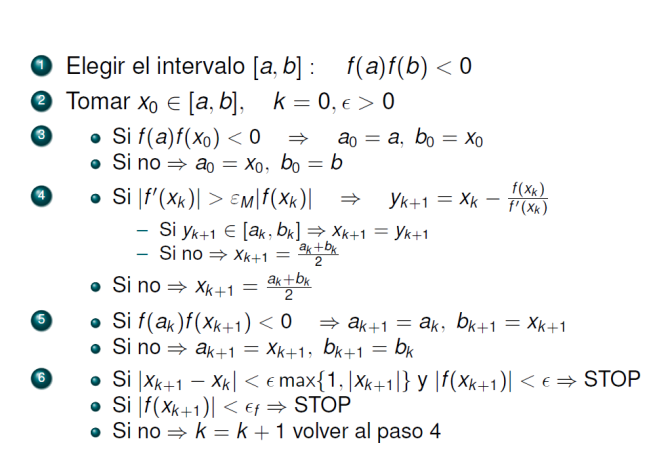

Una posible implementación:

**Ejercicio**: Resolvemos la ecuación $f(x)  = \cos(x) + 1 -x =0$ usando el método de Newton-bisección con tolerancia $\epsilon = 10^{-2}$ y la aproximación inicial $x_0 = 5$.

% escribe el código aquí 






#### Método de la secente-bisección

El método de la secante-bisección combina dos métodos (de la secante y de bisección) para mejorar la estabilidad y la velocidad de convergencia. La idea es utilizar el método de la secante para obtener una nueva aproximación y, si esta no cumple con ciertos criterios de mejora, usar el método de bisección para asegurar que la nueva aproximación esté en el intervalo correcto.

#### Comando `fzero`

La función `fzero` busca una raíz de la función$f(x)$ tal que$f(x) =0$. Este método es adecuado para funciones continuas y se basa en una combinación de los métodos de búsqueda de raíces como bisección, método de la secante y el método de interpolación inversa cuadrática.

**Sintaxis Básica**

- `fun`: Especifica la función cuya raíz se desea encontrar. Puede ser un handle a una función, una cadena que nombre una función, o una función anónima.

- `x0`: Punto inicial o estimación inicial para la raíz.

- `[x1, x2]`: Intervalo donde se busca la raíz, con $f(x1) \;y\;  f(x2)$ de signos opuestos.

- `root`: La raíz encontrada.

- `fval`: Valor de la función en la raíz encontrada (debe ser cercano a cero).

- `exitflag`: Indicador de éxito o razón de terminación.

- `output`: Estructura con información sobre el proceso de búsqueda.

Ejemplo: Resolvemos la ecuación $f(x)  = \cos(x) + 1 -x =0$ usando el comando `fzero` y la aproximación inicial $x_0 = 5$.

f =@(x) cos(x)+1-x;
x0 =3*pi/2;
[root, fval, exitflag, output] = fzero(f,x0)

## 2.5. Raíces de polinomios


$$$$p_n (x) = a_0 + a_1 x  + a_2 x^2 + \ldots + a_n x^n$$$$


En una ecuación de grado $$n$$, hay $$n$ $raíces reales o complejas. Se debe notar que esas raíces no necesariamente son distintas. Si $$n$$ es impar, hay al menos una raíz real. Si existen raíces complejas, éstas se encuentran por pares conjugados.

Todas las raíces satisfacen 

$$$ \frac{|a_0|}{b+|a_0|} \leq |x^*|\leq 1+\frac{c}{|a_n|},$$ $b = \max \left\{ |a_1|, |a_2|,\ldots,|a_n|\right\}, \; c = \max \left\{ |a_0|,|a_1|, |a_2|,\ldots,|a_{n-1}|\right\}$$.

#### Polinomios en MATLAB

En MATLAB, el tratamiento de polinomios se realiza de manera eficiente utilizando vectores para representar los coeficientes del polinomio, comenzando desde el coeficiente del término de mayor grado hasta el coeficiente del término independiente: `p = [a_n, a_{n-1}, ..., a_1, a_0];`

**Ejercicio:** Define en MATLAB los siguientes polinomios:

- 
$$$p(x) = x^5 +  3x^4 -23x^3  -51x^2 + 94x  $$$


- 
$$$p
(x) = x^3 -6x^2 + 11(x-6) $$$


- 
$$$p(x) = x^4   -13x^3   + 220x -400 $$$


- 
$$$p(x)= x^3   -2x -1 $$$


Para comprobar los resultados:

ejemplo_polinomios

Ir a "ejemplo_polinomios"

Las siguientes funciones permiten realizar una amplia gama de operaciones con polinomios en MATLAB, facilitando la manipulación y análisis de estos:

- [`poly`](https://es.mathworks.com/help/matlab/ref/poly.html): Construye polinomios con raíces específicas.

r = [1, 2, 3];
p = poly(r)  % Crea el polinomio (x-1)(x-2)(x-3)

- [`polyval`](https://es.mathworks.com/help/matlab/ref/polyval.html): Evalúa un polinomio.

p = [2, 3, -1, 5];  % Polinomio 2x^3 + 3x^2 - x + 5
x = 2;
y = polyval(p, x)  % Evalúa el polinomio en x = 2

- [`polyder`](https://es.mathworks.com/help/matlab/ref/polyder.html): Diferenciación polinomial.

p = [2, 3, -1, 5];  % Polinomio 2x^3 + 3x^2 - x + 5
dp = polyder(p)  % Derivada del polinomio

 - [`conv`](https://es.mathworks.com/help/matlab/ref/conv.html): Multiplicación de polinomios.

p1 = [1, 2, 1];  % Polinomio x^2 + 2x + 1
p2 = [1, -1];    % Polinomio x - 1
p3 = conv(p1, p2)  % Resultado de (x^2 + 2x + 1) * (x - 1)

 - [`deconv`](https://es.mathworks.com/help/matlab/ref/deconv.html): División de polinomios.

p1 = [1, -3, 2];  % Polinomio x^2 - 3x + 2
p2 = [1, -1];     % Polinomio x - 1
[q, r] = deconv(p1, p2)  % División de p1 entre p2, q es el cociente y r es el residuo

- [`roots`](https://es.mathworks.com/help/matlab/ref/roots.html): Encuentra raíces de polinomios.

p = [2, 3, -1, 5];  % Polinomio 2x^3 + 3x^2 - x + 5
r = roots(p)  % Encuentra las raíces del polinomio

La función `roots` utiliza el concepto de valores propios para encontrar las raíces de un polinomio. A continuación, se presenta otro método para encontrar raíces de polinomios, basado en iteraciones del método de Newton-Raphson, conocido como el método de Maehly.

#### Método de Maehly

Método básico (de Newton-Raphson): $$$x_{k+1} = x_k - \frac{p_n(x_k)}{p_n'(x_k)}$$$

Una vez calculada una raíz $$\xi_1$$, se inician las iteraciones en otro punto, pero  ¿cómo evitar

que las iteraciones converjan de nuevo hacia la misma raíz $$\xi_1$$?

Si se han calculado $$m$ $raíces $$\xi_1, \ldots, \xi_m$$, se aplica el método de Newton a la función


$$$$f(x) = \frac{p_n(x)}{(x-\xi_1) \cdot \ldots \cdot(x-\xi_m)}$$$$


Iteraciones del **método de Maehly**:


$$$$x_{k+1} = x_k - \frac{p_n(x_k)}{p_n'(x_k) - p_n(x_k) \sum_{j=1}^m \frac{1}{(x_k - \xi_j)}}$$$$


Una posible implementación del método de Maehly:

## Bibliografía

- [Chapra S.C.; Canale R. (2015) Métodos Numéricos para Ingenieros. Ed. McGRaw-Hill](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=436963) (Capítulos 5-8)

- [Mathews J.H., Fink K.D. (2000) Métodos Numéricos con MATLAB. Ed. Prentice Hall](https://catalogo.unican.es/cgi-bin/abnetopac?TITN=163396) (Capítulo 2)

Funciones auxiliares

1. Método de bisección

function [ x_r,k ,ak,bk] = biseccion( f, a, b, epsilon)
% f - función anónima cuya raíz se quiere aproximar: f(x) = 0
% a, b - los extremos del intervalo inicial
% epsilon - la tolerancia
% x_r - aproximación de la raíz
% k - número de iteraciones

if (f(a)*f(b)<0) % condición del Teorema de Bolzano
    N = 1 + round(log(b-a)-log(epsilon)/log(2)); % número máximo de iteraciones
    x_r = (a+b)/2; % punto medio
    for k = 1:N
        x_r = (a+b)/2;
        if (f(a)*f(x_r)<0)
            b = x_r;
        else
            a =x_r;
        end
        if abs(a-b)<epsilon || abs(f(x_r))<epsilon
            break
        end
    end
else
    fprintf("En intervalo inicial no cumple la condición del Teorema de Bolzano.\n")
end
ak = a; bk = b;
end

2. Método de Newton

function [x, k] = newton(f,fprime,x,epsilon)
N_max = 100; % número máximo de iteraciones
% bucle principal:
for k=1:N_max
    df = fprime(x);
    if abs(df)>eps
        % calculamos el incremento dx = f(x)/f'(x):
        dx  = f(x)/fprime(x);
        x = x - dx;
        % comprobamos los criterios de paro:
        if abs(dx)< epsilon * max(1, abs(x)) || abs( f(x))<epsilon
            break;
        end
    else
        fprintf("El método diverge!")
        x = NaN; 
        break
    end
end
end

3. Ejemplo de definición de los polinomios:

function [] = ejemplo_polinomios()
p1 = [1 3 -23 -51 94 0];
vect2poly(p1);
disp(p1)
p2 = [1 -6 11 -66];
vect2poly(p2);
disp(p2)
p3 = [1 -13 0 220 -400];
vect2poly(p3);
disp(p3)
p4 = [1 0 -2 -1];
vect2poly(p4);
disp(p4)
end

function [] = vect2poly(v)
n = length(v);
fprintf("\n")
str1 = ["Polinomio: p(x) = ",num2str(v(1)),'x^', num2str(n-1)];
for k = 2:n-1
    if(v(k) >0)
        str1 = [str1, '+',num2str(v(k)),'x^', num2str(n-k)];
    elseif v(k) <0
           str1 = [str1,'-', num2str(-v(k)),'x^', num2str(n-k)];
    end
end
    if(v(n) >0)
        str1 = [str1, '+',num2str(v(n))];
    elseif v(n) <0
           str1 = [str1,'-', num2str(-v(n))];
    end

fprintf("%s",str1)
fprintf("\n")
end